# **Metoda kierunków sprzężonych Hooke"a-Jeevesa**

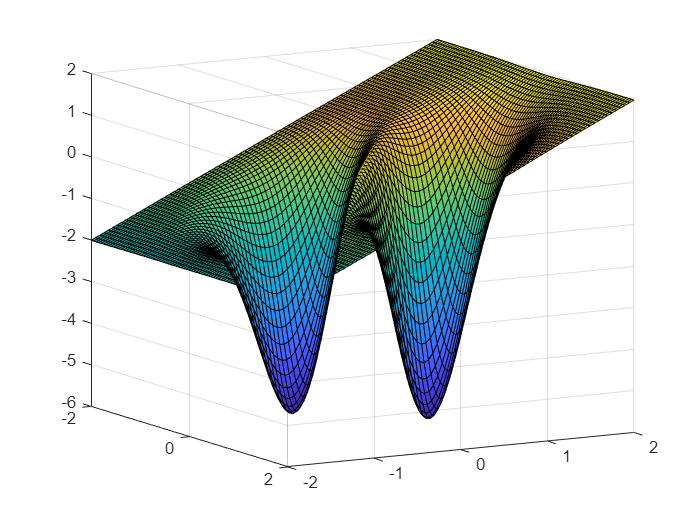

clearvars all; close all;

f = @(x) x(1)-(4*(x(1)+x(2)).*exp(-x(1).^2 - x(2).^2)+0.1).^2;
t = linspace(-2, 2, 80);
[xx, yy] = meshgrid(t, t);
z = arrayfun(@(x,y) f([x,y]), xx, yy);

figure()
surf(xx, yy, z); view([29.64 -11.83])



P1 = [-1 -1];
P2 = [0 0];
P3 = [3 3];
P4 = [-0.8 1];
P5 = [-2 -1];

s = 0.5;
alpha = 0.5; 
epsilon = 1e-6;

X1 = hooke_jeeves(f, P1, s, alpha, epsilon)

X1 =    -0.5334   -0.4890


X2 = hooke_jeeves(f, P2, s, alpha, epsilon)

X2 =     0.4694    0.5103


X3 = hooke_jeeves(f, P3, s, alpha, epsilon)

X3 =    -0.5334   -0.4890


X4 = hooke_jeeves(f, P4, s, alpha, epsilon)

X4 =     0.4694    0.5103


%hooke_jeeves(f, P5, s, alpha, epsilon) %inf loop

X = [X1; X2; X3; X4];

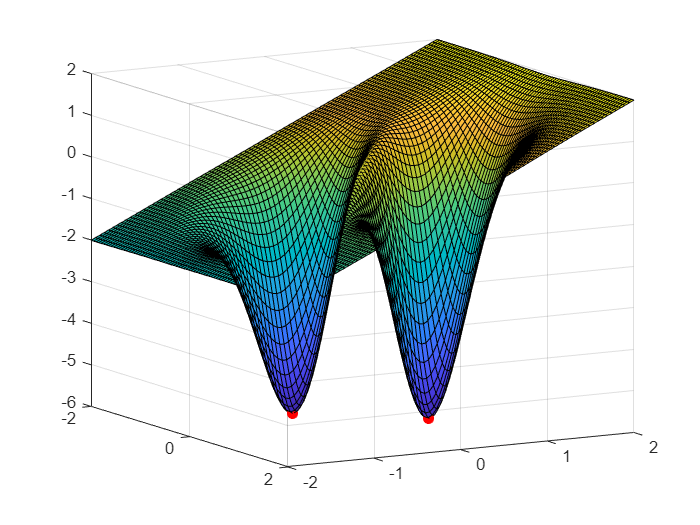

figure()
surf(xx, yy, z);
view([29.64 -11.83]); hold on;
for i = 1:length(X)
    plot3(X(i,1), X(i,2), f(X(i, :)), 'r.', 'MarkerSize', 20)
end
hold off